Erdos-Renyi demo: degree law, giant component, and small-world scaling

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_ER_PROPERTIES Demo class material for Erdos-Renyi graphs.
%
% Topics:
%   1) degree distribution
%   2) giant component + small tree-like components
%   3) small-world scaling of distances with n

rng(1);


1) Degree distribution: empirical vs exact Binomial vs Poisson limit

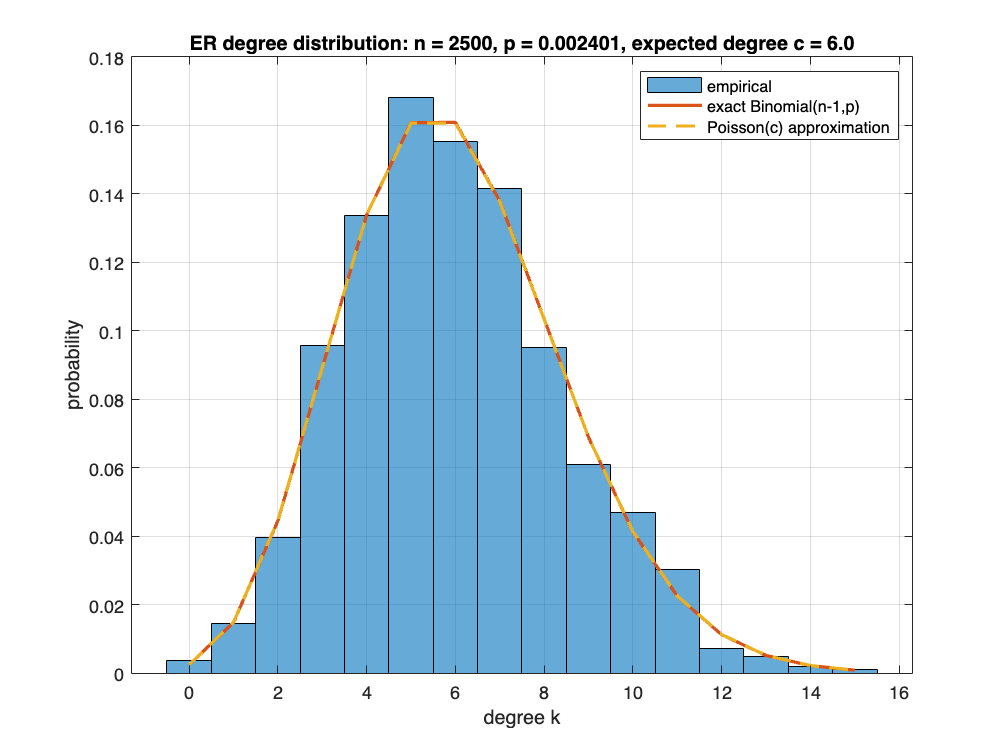

n = 2500;
c = 6;
p = c / (n - 1);
G = make_er_graph(n, p);
k = degree(G);

kvals = (0:max(k)).';
binomP = exp(gammaln(n) - gammaln(kvals + 1) - gammaln(n - kvals) ...
    + kvals .* log(p) + (n - 1 - kvals) .* log(1 - p));
poisP = exp(-c + kvals .* log(c) - gammaln(kvals + 1));

figure('Name', 'ER degree distribution');
histogram(k, 'Normalization', 'probability', 'BinMethod', 'integers', ...
    'DisplayStyle', 'bar');
hold on;
plot(kvals, binomP, 'LineWidth', 1.8);
plot(kvals, poisP, '--', 'LineWidth', 1.8);
hold off;
xlabel('degree k');
ylabel('probability');
title(sprintf('ER degree distribution: n = %d, p = %.4g, expected degree c = %.1f', n, p, c));
legend('empirical', 'exact Binomial(n-1,p)', 'Poisson(c) approximation', ...
    'Location', 'northeast');
grid on;

2) Giant component and small tree-like components

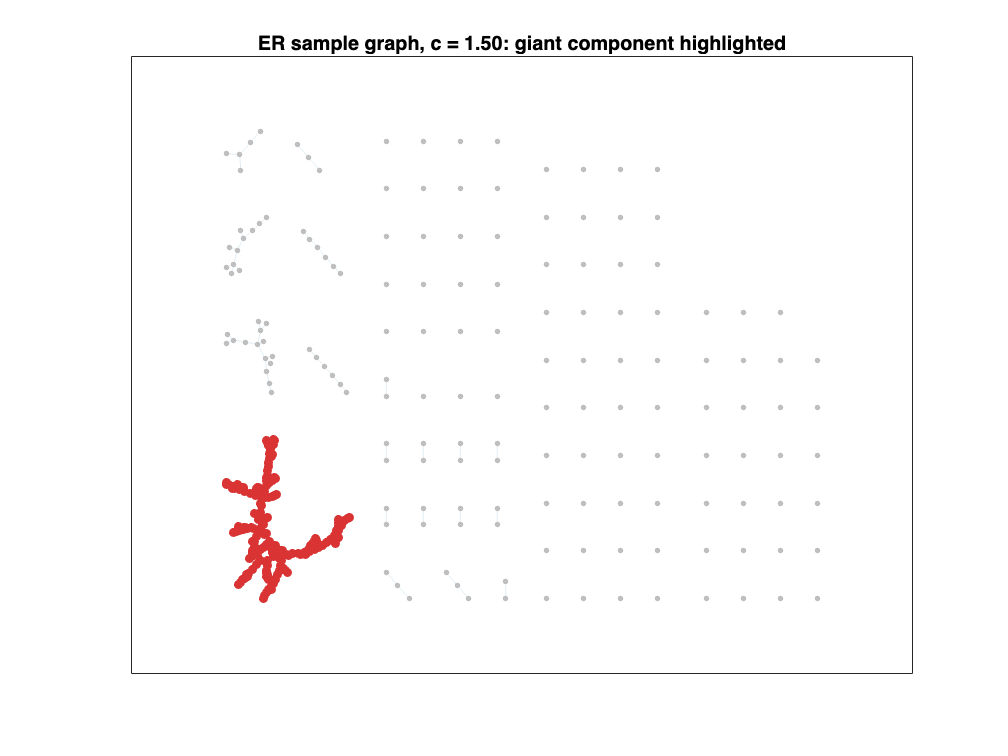

nVis = 350;
cSuper = 1.5;
pSuper = cSuper / (nVis - 1);
Gvis = make_er_graph(nVis, pSuper);

bins = conncomp(Gvis);
compSizes = accumarray(bins.', 1);
[~, giantID] = max(compSizes);
giantNodes = find(bins == giantID);

figure('Name', 'ER giant component visualization');
h = plot(Gvis, 'Layout', 'force', 'NodeLabel', {}, ...
    'NodeColor', [0.75 0.75 0.75], 'EdgeAlpha', 0.12);
highlight(h, giantNodes, 'NodeColor', [0.85 0.20 0.20], 'MarkerSize', 4);
title(sprintf('ER sample graph, c = %.2f: giant component highlighted', cSuper));

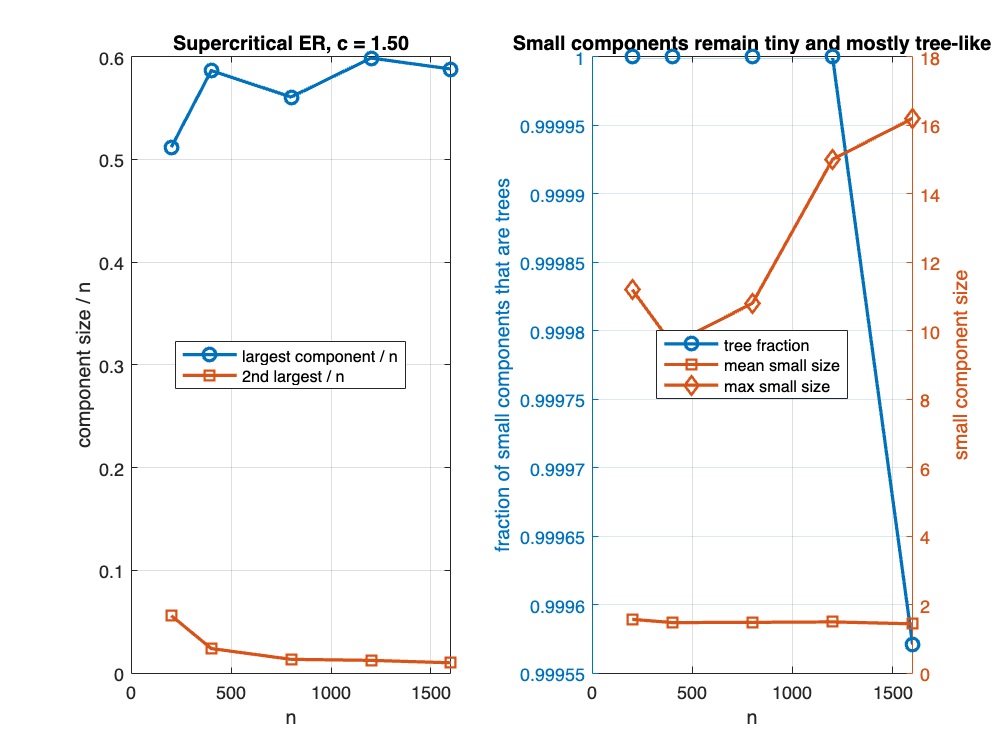


nVals = [200 400 800 1200 1600];
reps = 5;

giantFrac = zeros(numel(nVals), 1);
secondFrac = zeros(numel(nVals), 1);
treeFracSmall = zeros(numel(nVals), 1);
meanSmallSize = zeros(numel(nVals), 1);
maxSmallSize = zeros(numel(nVals), 1);

for ii = 1:numel(nVals)
    nNow = nVals(ii);
    pNow = cSuper / (nNow - 1);

    giantTmp = 0;
    secondTmp = 0;
    treeTmp = 0;
    meanSmallTmp = 0;
    maxSmallTmp = 0;

    for r = 1:reps
        Gnow = make_er_graph(nNow, pNow);
        bins = conncomp(Gnow);
        compSizes = accumarray(bins.', 1);
        numComp = numel(compSizes);

        compEdges = zeros(numComp, 1);
        isTree = false(numComp, 1);

        for cc = 1:numComp
            idx = find(bins == cc);
            Hc = subgraph(Gnow, idx);
            compEdges(cc) = numedges(Hc);
            isTree(cc) = (numedges(Hc) == numnodes(Hc) - 1);
        end

        [sortedSizes, ord] = sort(compSizes, 'descend');
        giantTmp = giantTmp + sortedSizes(1) / nNow;

        if numel(sortedSizes) >= 2
            secondTmp = secondTmp + sortedSizes(2) / nNow;
        end

        keep = true(numComp, 1);
        keep(ord(1)) = false;

        if any(keep)
            treeTmp = treeTmp + mean(isTree(keep));
            meanSmallTmp = meanSmallTmp + mean(compSizes(keep));
            maxSmallTmp = maxSmallTmp + max(compSizes(keep));
        end
    end

    giantFrac(ii) = giantTmp / reps;
    secondFrac(ii) = secondTmp / reps;
    treeFracSmall(ii) = treeTmp / reps;
    meanSmallSize(ii) = meanSmallTmp / reps;
    maxSmallSize(ii) = maxSmallTmp / reps;
end

figure('Name', 'ER component scaling');
tiledlayout(1, 2);

nexttile;
plot(nVals, giantFrac, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
plot(nVals, secondFrac, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold off;
xlabel('n');
ylabel('component size / n');
title(sprintf('Supercritical ER, c = %.2f', cSuper));
legend('largest component / n', '2nd largest / n', 'Location', 'best');
grid on;

nexttile;
yyaxis left;
plot(nVals, treeFracSmall, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
ylabel('fraction of small components that are trees');

yyaxis right;
plot(nVals, meanSmallSize, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
plot(nVals, maxSmallSize, 'd-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold off;
ylabel('small component size');
xlabel('n');
title('Small components remain tiny and mostly tree-like');
legend('tree fraction', 'mean small size', 'max small size', 'Location', 'best');
grid on;

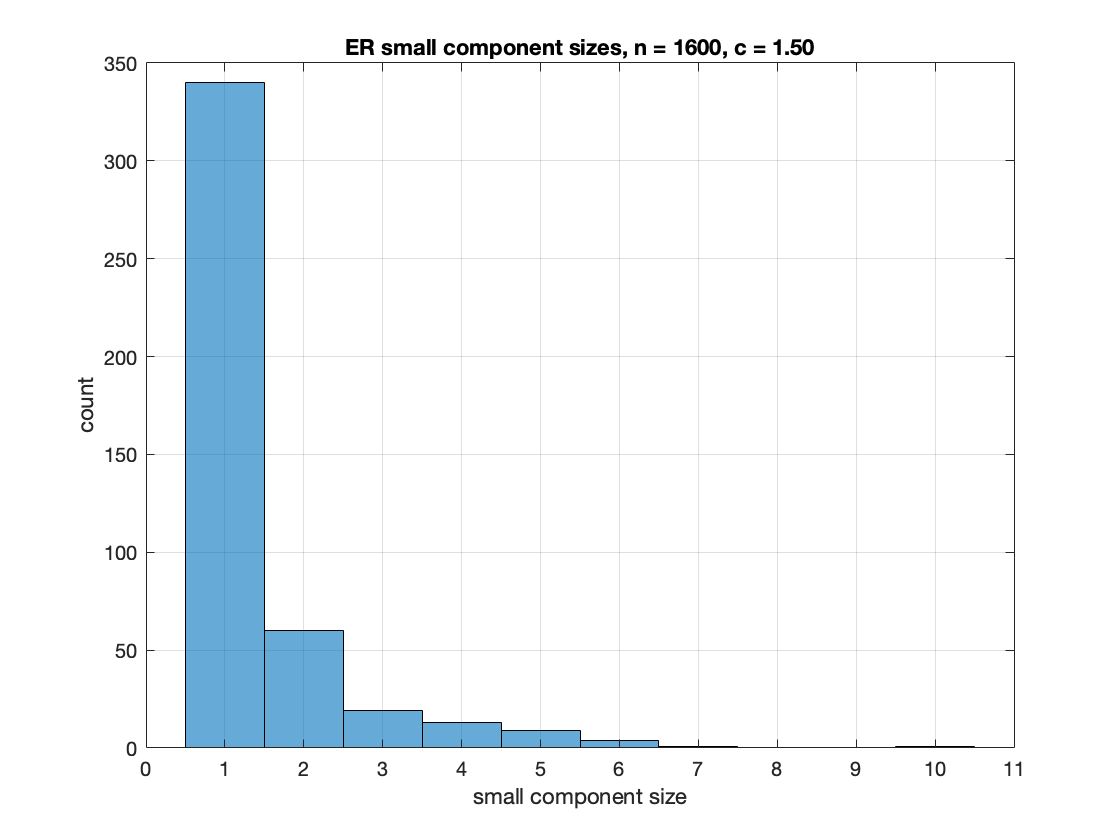


% Histogram of small component sizes for one large sample.
nHist = 1600;
Ghist = make_er_graph(nHist, cSuper / (nHist - 1));
bins = conncomp(Ghist);
compSizes = accumarray(bins.', 1);
[~, ord] = sort(compSizes, 'descend');
compSizes(ord(1)) = [];  % remove giant component

figure('Name', 'ER small component size histogram');
histogram(compSizes, 'BinMethod', 'integers');
xlabel('small component size');
ylabel('count');
title(sprintf('ER small component sizes, n = %d, c = %.2f', nHist, cSuper));
grid on;

3) Small-world scaling: distances grow roughly like log n

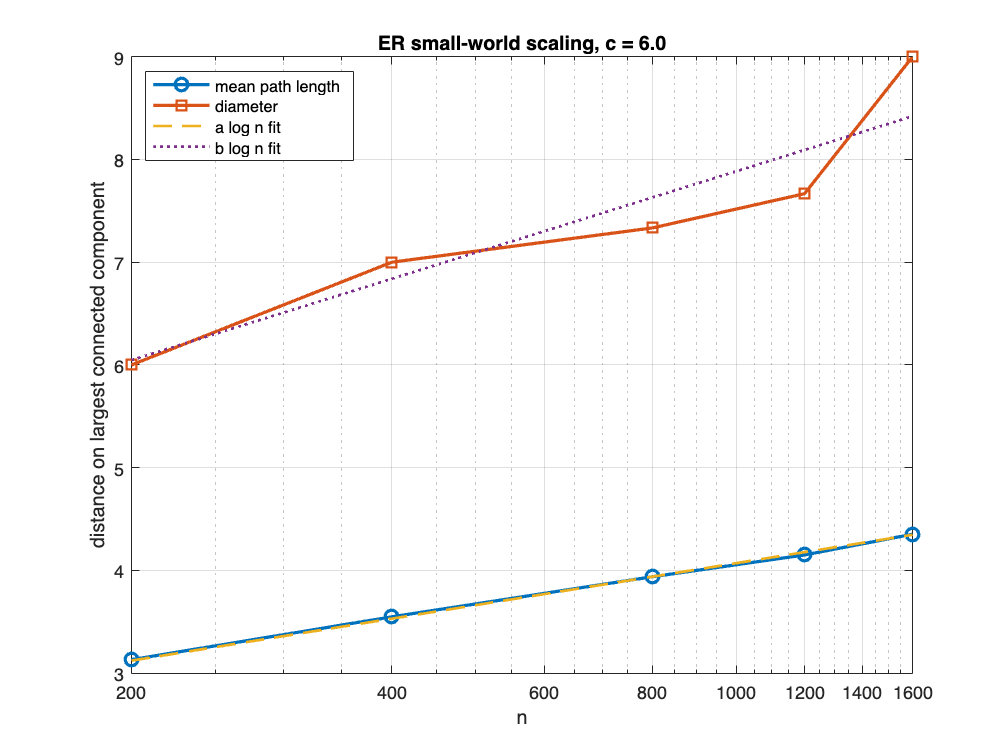

nValsSW = [200 400 800 1200 1600];
cSW = 6;
repsSW = 3;

meanPath = zeros(numel(nValsSW), repsSW);
diamVal = zeros(numel(nValsSW), repsSW);

for ii = 1:numel(nValsSW)
    nNow = nValsSW(ii);
    pNow = cSW / (nNow - 1);

    for r = 1:repsSW
        Gnow = make_er_graph(nNow, pNow);
        [L, D] = path_length_stats(Gnow, true);
        meanPath(ii, r) = L;
        diamVal(ii, r) = D;
    end
end

meanPathAvg = mean(meanPath, 2);
diamAvg = mean(diamVal, 2);

x = log(nValsSW(:));
aL = (x \ meanPathAvg);
aD = (x \ diamAvg);

figure('Name', 'ER small-world scaling');
semilogx(nValsSW, meanPathAvg, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
semilogx(nValsSW, diamAvg, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
semilogx(nValsSW, aL * log(nValsSW(:)), '--', 'LineWidth', 1.5);
semilogx(nValsSW, aD * log(nValsSW(:)), ':', 'LineWidth', 1.5);
hold off;
xlabel('n');
ylabel('distance on largest connected component');
title(sprintf('ER small-world scaling, c = %.1f', cSW));
legend('mean path length', 'diameter', 'a log n fit', 'b log n fit', ...
    'Location', 'northwest');
grid on;


fprintf('\nER demo finished.\n');


ER demo finished.


fprintf('For sparse ER with p = c/(n-1): degree ~ Binomial and approx Poisson when n is large.\n');

For sparse ER with p = c/(n-1): degree ~ Binomial and approx Poisson when n is large.


fprintf('For c > 1: a giant component appears; the non-giant components remain tiny and mostly tree-like.\n');

For c > 1: a giant component appears; the non-giant components remain tiny and mostly tree-like.


fprintf('Distances on the giant component grow slowly, roughly logarithmically in n.\n\n');

Distances on the giant component grow slowly, roughly logarithmically in n.

